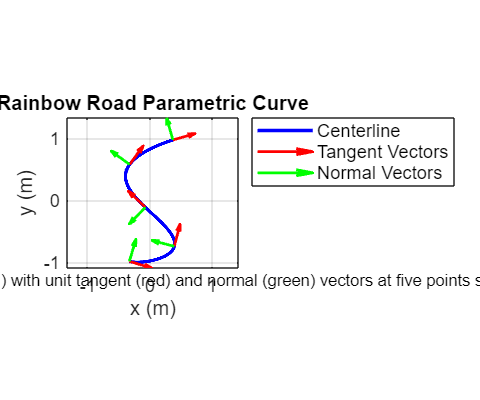


% Define parameter u with high resolution
u = linspace(0, 3.2, 2000);

% Parametric curve
x = 0.3960 * cos(2.65 * (u + 1.4));
y = -0.99 * sin(u + 1.4);

% Tangent vector components
dx_du = -1.0494 * sin(2.65 * (u + 1.4)); % d/du [x(u)]
dy_du = -0.99 * cos(u + 1.4);            % d/du [y(u)]
mag = sqrt(dx_du.^2 + dy_du.^2);         % Magnitude of r'(u)

% Unit tangent vectors
Tx = dx_du ./ mag;
Ty = dy_du ./ mag;

% Unit normal vectors (90° counterclockwise rotation)
Nx = -Ty;
Ny = Tx;

% Approximate arc length for even spacing of vectors
ds = cumtrapz(u, mag); % Cumulative arc length
s_total = ds(end);     % Total arc length
s_points = linspace(0, s_total, 5); % 5 evenly spaced points by arc length
u_points = interp1(ds, u, s_points); % Corresponding u values

% Interpolate positions and vectors at these points
x_points = interp1(u, x, u_points);
y_points = interp1(u, y, u_points);
Tx_points = interp1(u, Tx, u_points);
Ty_points = interp1(u, Ty, u_points);
Nx_points = interp1(u, Nx, u_points);
Ny_points = interp1(u, Ny, u_points);

% Plot
figure('Position', [100, 100, 600, 500], 'Color', 'white');
plot(x, y, 'b-', 'LineWidth', 2, 'DisplayName', 'Centerline');
hold on;
quiver(x_points, y_points, Tx_points, Ty_points, 0.4, 'r', 'LineWidth', 1.5, ...
    'MaxHeadSize', 0.3, 'DisplayName', 'Tangent Vectors');
quiver(x_points, y_points, Nx_points, Ny_points, 0.4, 'g', 'LineWidth', 1.5, ...
    'MaxHeadSize', 0.3, 'DisplayName', 'Normal Vectors');
axis equal; grid on;
xlabel('x (m)'); ylabel('y (m)');
title('Rainbow Road Parametric Curve', 'FontSize', 12);
legend('Location', 'bestoutside', 'FontSize', 10);
caption = sprintf('The parametric curve defining the Rainbow Road centerline (u ∈ [0, 3.2]) with unit tangent (red) and normal (green) vectors at five points spaced by arc length, illustrating path geometry.');
text(0, -1.3, caption, 'FontSize', 9, 'HorizontalAlignment', 'center', 'Interpreter', 'none');
set(gca, 'FontSize', 10);
hold off;